% #01
% P1P2=lambda/2=5 cm
% f-?
clear
syms c lambda
f=c/lambda

$$f = \frac{c}{\lambda }$$

digits(3)
f1=vpa(subs(f,[c lambda],[3e8 2*0.05]))

$$f1 = 3.0\,10^{9}$$

% 3.0e9 Hz = 3 GHz

% #02
% L=0.12 m
% lambda/2=0.04 m
% u=30 m/s

clear
% a)
syms u lambda
f=u/lambda

$$f = \frac{u}{\lambda }$$

digits(3)
f1=vpa(subs(f,[u lambda],[30 0.08]))

$$f1 = 375.0$$

% 375.0 Hz

% b)
syms L n
lambdan=2*L/n

$$lambdan = \frac{2\,L}{n}$$

lambda1=vpa(subs(lambdan,[L n],[0.12 1]))

$$lambda1 = 0.24$$

% 0.24 m
lambda2=vpa(subs(lambdan,[L n],[0.12 2]))

$$lambda2 = 0.12$$

% 0.12 m

f=u/lambda

$$f = \frac{u}{\lambda }$$

f1=vpa(subs(f,[u lambda],[30 lambda1]))

$$f1 = 125.0$$

% 125.0 Hz
f2=vpa(subs(f,[u lambda],[30 lambda2]))

$$f2 = 250.0$$

% 250.0 Hz
f3=vpa(subs(f,[u lambda],[30 0.08]))

$$f3 = 375.0$$

% 375.0 Hz

% c)
syms mu u
T=mu*u^2

$$T = \mu \,u^{2}$$

T1=vpa(subs(T,[mu u],[0.024/0.12 30]))

$$T1 = 180.0$$

% 180.0 N

% #03
% d = 2 m
% f = 1000 Hz
% D = 4 m

% First node observed when
% r2-r1=lambda/2
% r2-r1=d*sin(theta) => sin(theta)=lambda/(2*d)
clear
syms u f d D theta
lambda=u/f

$$lambda = \frac{u}{f}$$

digits(3)
lambda1=vpa(subs(lambda,[u,f],[330 1000]))

$$lambda1 = 0.33$$

% 0.33 m
theta=asin(lambda/(2*d))

$$theta = \mathrm{asin}\left(\frac{u}{2\,d\,f}\right)$$

theta1=subs(theta,[lambda d],[lambda1 2])

$$theta1 = 0.0826$$

% 0.0826
syms D theta
y=D*tan(theta)

$$y = \text{D}\,\tan\left(\theta \right)$$

y1=vpa(subs(y,[D,theta],[4 theta1]))

$$y1 = 0.331$$

% 0.33 m

% #04
% phi=k*d*sin(theta)-pi/2
syms theta phi
phi1=pi/2*(sin(theta)-1)

$$phi1 = \frac{\pi \,\left(\sin\left(\theta \right)-1\right)}{2}$$

syms I0 N
I=I0*sin(N*phi/2)^2/sin(phi/2)^2

$$I = \frac{I_{0}\,{\sin\left(\frac{N\,\phi }{2}\right)}^{2}}{{\sin\left(\frac{\phi }{2}\right)}^{2}}$$

I=subs(I,[N phi],[4 phi1])

$$I = \frac{I_{0}\,{\sin\left(\pi \,\left(\sin\left(\theta \right)-1\right)\right)}^{2}}{{\sin\left(\frac{\pi \,\left(\sin\left(\theta \right)-1\right)}{4}\right)}^{2}}$$

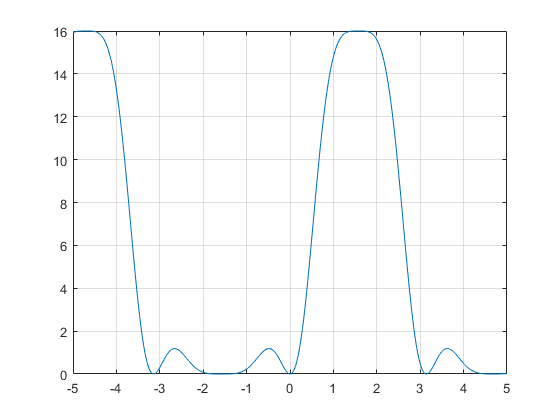

% (I0*sin(pi*(sin(theta) - 1))^2)/sin((pi*(sin(theta) - 1))/4)^2
fplot(subs(I,I0,1))
grid on

% #05
% n=13400 lines/inch
% lambda=5893 A
clear
syms D n
d=D/n

$$d = \frac{\text{D}}{n}$$

digits(3)
d1=vpa(subs(d,[D n],[2.54e-2 13400]))

$$d1 = 1.9\,10^{-6}$$

% 1.9e-6 m

syms n lambda d
sin_theta=n*lambda/d

$$sin\_theta = \frac{\lambda \,n}{d}$$

sin_theta1=vpa(subs(sin_theta,[n lambda d],[1 5893e-10 d1]))

$$sin\_theta1 = 0.311$$

% 0.311
theta1=vpa(asin(sin_theta1)*180/pi)

$$theta1 = 18.1$$

% 18.1 grad

sin_theta2=vpa(subs(sin_theta,[n lambda d],[2 5893e-10 d1]))

$$sin\_theta2 = 0.622$$

% 0.622
theta2=vpa(asin(sin_theta2)*180/pi)

$$theta2 = 38.4$$

% 38.4 grad

sin_theta3=vpa(subs(sin_theta,[n lambda d],[3 5893e-10 d1]))

$$sin\_theta3 = 0.933$$

% 0.933
theta3=vpa(asin(sin_theta3)*180/pi)

$$theta3 = 68.9$$

% 68.9 grad

% #06
clear
lambda=5893 

lambda =         5893


lambda1=5890

lambda1 =         5890


lambda2=5896

lambda2 =         5896



D_lambda=lambda2-lambda1

D_lambda =      6


digits(3)
vpa(lambda/D_lambda)

$$ans = 982.0$$

%   982
% 13400 (from sample 5) > 982

% #07
clear
% y_dif=theta_min*D=lambda/u*D
syms u lambda D
y=u+lambda*D/u

$$y = u+\frac{\text{D}\,\lambda }{u}$$

dy=diff(y,u)

$$dy = 1-\frac{\text{D}\,\lambda }{u^{2}}$$

% 1 - (D*lambda)/u^2=0
u0=solve(dy,u)

$$u0 = \left(\begin{array}{c} \sqrt{\text{D}\,\lambda }\\ -\sqrt{\text{D}\,\lambda } \end{array}\right)$$

% u0=(D*lambda)^(1/2)

% #08
% f = 1000 MHz
% R = 100 ly = 9.46e17 m
% D = 3 km = 3e3 m
clear
syms D R
theta=D/R

$$theta = \frac{\text{D}}{R}$$

digits(3)
theta1=vpa(subs(theta,[D R],[3e3 100*9.46e15]))

$$theta1 = 3.17\,10^{-15}$$

% 3.17e-15 rad

lambda1=3e8/1e9

lambda1 =    0.300000000000000


%     0.3 m

syms lambda
d=lambda/(2*theta)

$$d = \frac{R\,\lambda }{2\,\text{D}}$$

d1=vpa(subs(d,[lambda theta],[lambda1 theta1]))

$$d1 = 4.73\,10^{13}$$

% 4.73e13 m = 5.0e-3 ly
